clear;clc;close all
layerfolder='../Tool_landscape/data/layers/';%route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 6.460387 seconds.


InfoInitialPoint = InitialPoint(Dimensions,true)

InfoInitialPoint = struct with fields:
                 idx: [1 306593 306590 306589 306588 306587 306586 306585 306583 306584 306581 306582 305660 305661 305662 305664 305656 305659 305663 305611 305612 305655 305654 305665 305651 305652 305667 305613 305666 305657 305614 305615 305649 … ]
    SortNormDistance: [1 1 0.3497 0.3490 0.3478 0.3470 0.3468 0.3456 0.3446 0.3445 0.3439 0.3437 0.3436 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 0.3435 … ]


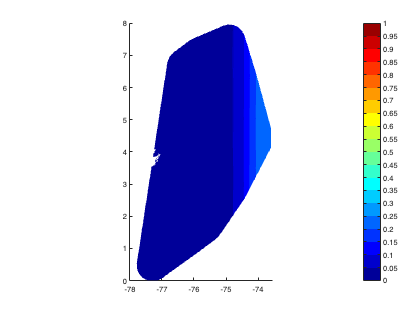

MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true);

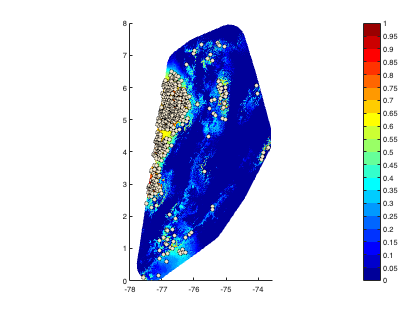

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 500, -3, true, 'GenSP', true, true);

----Finding clusters----


2 clusters identified


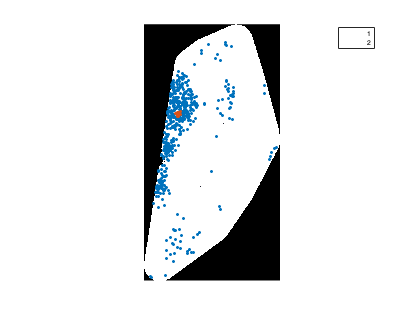

Elapsed time is 5.249171 seconds.
----Finding correlation----
Elapsed time is 9.635109 seconds.
----Creating predictors----
----Finding correlation----
Elapsed time is 10.811474 seconds.
----Creating predictors----
¡All done!
Elapsed time is 10.990751 seconds.


close all
[data,outland] = bnm_prep(T, Dimensions, false, 0.7, true, false);

data{1}.T2

ans = 498×22 table
    Name      LONG        LAT      bio1    bio2    bio3    bio4    bio5    bio6    bio7    bio8    bio9    bio10    bio11    bio12    bio13    bio14    bio15    bio16    bio17    bio18    bio19
    _____    _______    _______    ____    ____    ____    ____    ____    ____    ____    ____    ____    _____    _____    _____    _____  

----Modeling----


ij = 1

-Model 1


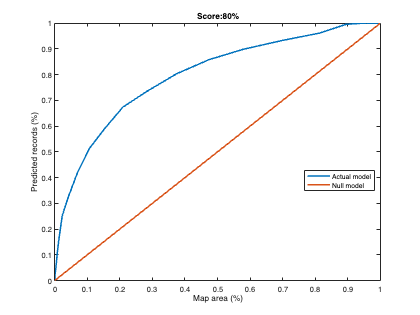

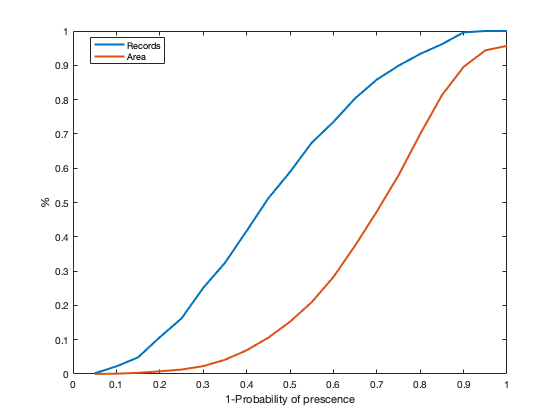

Elapsed time is 2.433147 seconds.


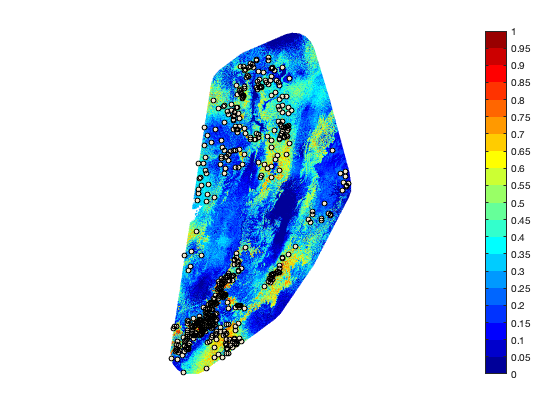

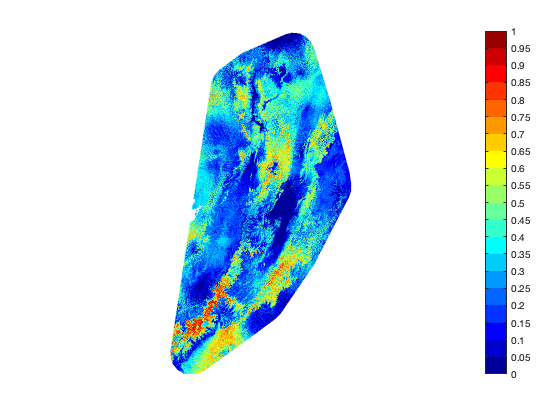

dataf = bnm_modeling(data, '', true, 4, false);

close all

Error using DetectMultVarOutliers
Incorrect entry for 1st input argument (X)

Error in predictpca (line 40)
    [~,~,RD,chi_crt]=DetectMultVarOutliers(pin);

Error in bnm_modeling2 (line 26)
[map3,score]=predictpca(Tpca,Z,R,indicators,vars,show,outlier,outlier2);

show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=true;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
data = bnm_modeling2(data{1},show,outlier,outlier2)